clearvars;
cd(fileparts(matlab.desktop.editor.getActiveFilename));
addpath(genpath(cd));

Freqs = CleanDir(['SampleData' filesep 'EEG']);

model = {'StableSimpleQ' 'Neg2Q' 'Pun2Q'};

for m = 1:length(model)

    Deci.Analysis.Freq.Extra.Corr.Behavior = {[model{m} '\mEV'] [model{m} '\mPE'] [model{m} '\mR'] ...
                                             [model{m} '\sEV'] [model{m} '\sPE'] [model{m} '\sR'] };
    Deci.Analysis.Freq.Extra.Corr.categorical = [4 5 6];
    Deci.Analysis.Freq.Extra.Corr.signed = [4 5 6];

    %x + x4*x9 + x3*x8 x1*x6 + + x3*x8-x8 + x1*x6
    states = [20 21 23 24 120 121];

    for subj = 1:length(Freqs)

        load(['SampleData' filesep 'EEG' filesep Freqs{subj} '\Fdb Onset\All\FCz.mat']);

        data{subj} = cat(1,rawfreq.trialpow{:});

        load(['SampleData' filesep 'EEG' filesep Freqs{subj} '\Stim Onset\All\FCz.mat']);

        bsl{subj} = nanmean(cat(1,rawfreq.trialpow{:}),1);

        data{subj} = [data{subj} - bsl{subj}]./bsl{subj};
        %data{subj} = [data{subj} - bsl{subj}]; %./bsl{subj};

        b = load(['SampleData' filesep 'Extra' filesep model{m} '\S\' filesep Freqs{subj} '\All.mat']);


        for behv = 1:length(Deci.Analysis.Freq.Extra.Corr.Behavior)

            load(['SampleData' filesep 'Extra' filesep Deci.Analysis.Freq.Extra.Corr.Behavior{behv} filesep Freqs{subj} '\All.mat']);

            bparam{behv} = cat(2,param{:})';
            bparam{behv} = bparam{behv}(cat(1,rawfreq.trialnums{:}));
            if ismember(behv,Deci.Analysis.Freq.Extra.Corr.signed)
                bparam{behv}(bparam{behv} == -1) = 2;
                bparam{behv}(bparam{behv} == 0) = 1;
            end

            for stat = 1:length(states)

                blk = 1;
                for block = 1:length(b.param)



                    if ismember(states(stat),b.param{block})
                        pos = ismember(b.param{block},states(stat));

                        blkparam{behv}(stat,subj,blk,:) = nan([40 1]);

                        blkparam{behv}(stat,subj,blk,:) = [param{block}(pos) nan([1 40-length(param{block}(pos))])];

                        blk = blk + 1;
                    else
                        continue
                    end

                end

            end


        end

        behav{subj} = cat(2,bparam{:});

    end

    brain = cat(1,data{:});
    behavior = cat(1,behav{:});

    BehvTitles = {'mEV' 'mPe' 'mR'...
        'sEV' 'sPe' 'sR' 'brain'};


    Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1  + mPe*sPe  + mEV*sEV' %+ mR + sR;

    BBCorr = array2table([behavior brain],'VariableNames',BehvTitles);


    mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
    %mdl2 = fitlm(BBCorr,'brain ~ 1 + mPe','CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

    % mdl2 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'PEnter',0)
    % mdl3 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
    % mdl4 = stepwiselm(BBCorr,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
    %
    % mdl5 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'Criterion','aic')

    %
    % Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mEV_next' 'StableDoubleNegQ\maEV' 'StableDoubleNegQ\mR' ...
    %                                           'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sEV_next' 'StableDoubleNegQ\saEV' 'StableDoubleNegQ\sR'};
end

Deci = struct with fields:
    Analysis: [1×1 struct]


mdl = Linear regression model:
    brain ~ 1 + mEV*sEV + mPe*sPe

Estimated Coefficients:
                    Estimate        SE          tStat        pValue  
                   __________    _________    _________    __________

    (Intercept)      -0.28343     0.064099      -4.4218    1.2179e-05
    mEV            -0.0059478    0.0045018      -1.3212       0.18708
    mPe             -0.015671    0.0085363      -1.8358      0.067019
    sEV_2          -0.0078912     0.080902    -0.097541       0.92234
    sPe_2            0.030182     0.092273       0.3271       0.74374
    mEV:sEV_2       0.0095163    0.0081622       1.1659       0.24425
    mPe:sPe_2       0.0070158     0.013644      0.51421       0.60735


Number of observations

Deci = struct with fields:
    Analysis: [1×1 struct]


mdl = Linear regression model:
    brain ~ 1 + mEV*sEV + mPe*sPe

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)      -0.24425     0.070912     -3.4444    0.00062374
    mEV            -0.0079018    0.0049041     -1.6112        0.1078
    mPe             -0.015959    0.0083017     -1.9223      0.055168
    sEV_2            -0.06362     0.083017    -0.76634       0.44386
    sPe_2           -0.026477     0.080724      -0.328       0.74306
    mEV:sEV_2        0.014997    0.0081002      1.8515      0.064732
    mPe:sPe_2        0.011054     0.012749     0.86702       0.38637


Number of observations: 476, Er

Deci = struct with fields:
    Analysis: [1×1 struct]


mdl = Linear regression model:
    brain ~ 1 + mEV*sEV + mPe*sPe

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    _________    ________    __________

    (Intercept)      -0.26261     0.070234     -3.7391    0.00020751
    mEV            -0.0068264    0.0049582     -1.3768       0.16924
    mPe             -0.014803    0.0084407     -1.7537      0.080127
    sEV_2           -0.051505     0.081795    -0.62969       0.52921
    sPe_2           -0.046604     0.081391    -0.57259        0.5672
    mEV:sEV_2        0.013453    0.0081048      1.6599      0.097604
    mPe:sPe_2        0.015582     0.012717      1.2254       0.22106


Number of observations: 476, Er

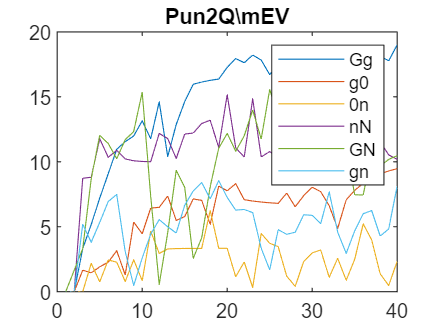

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


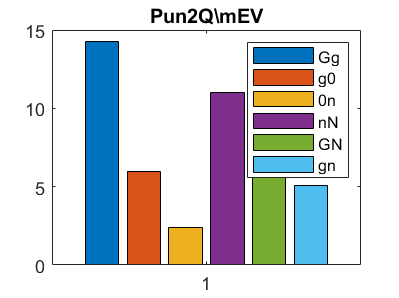

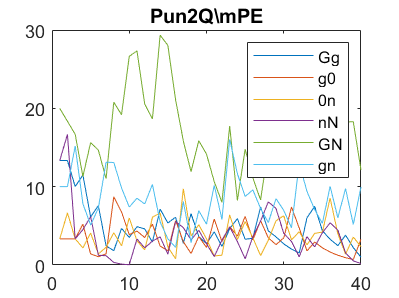

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


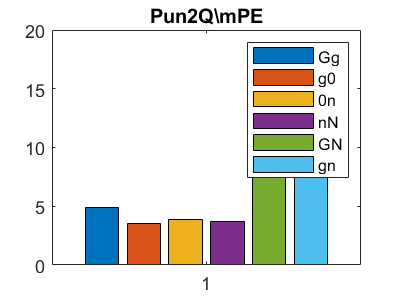

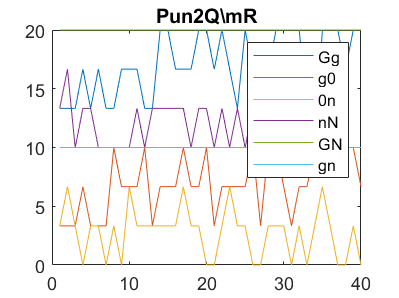

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


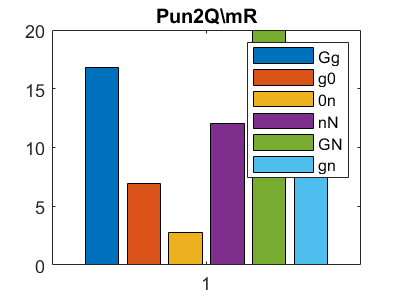

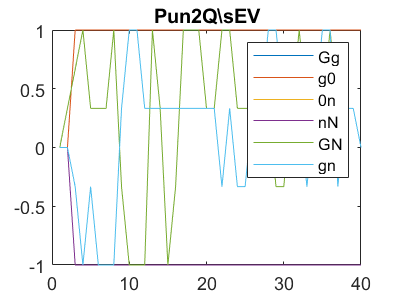

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


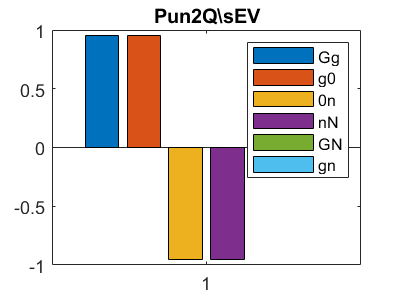

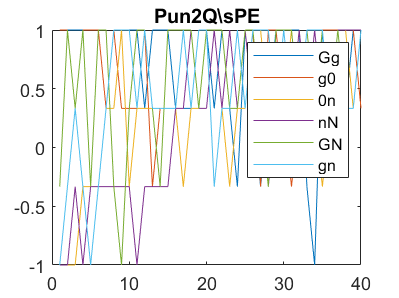

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


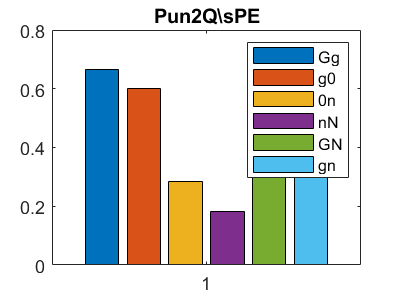

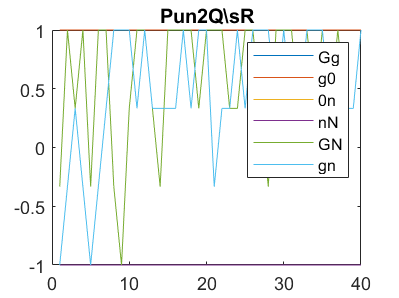

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


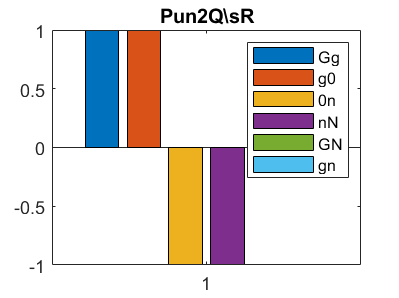


    statenames = {'Gg' 'g0' '0n' 'nN' 'GN' 'gn'};
    for blk = 1:length(blkparam)

        dat = squeeze(nanmean(nanmean(blkparam{blk},2),3));

        figure;
        plot(dat')
        title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
        legend(statenames)

        figure;
        dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4));
        CleanBars(dat')
        title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
        legend(statenames)
    end

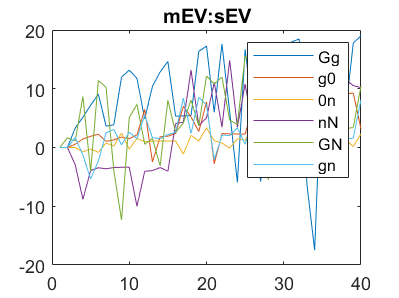

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


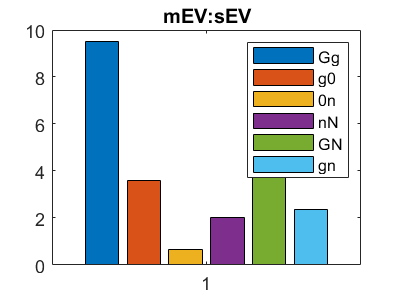

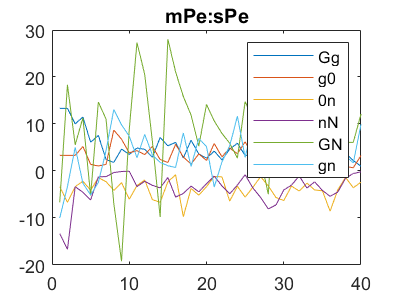

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


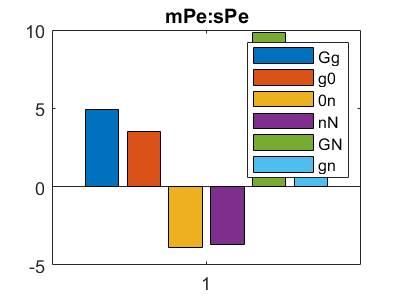

Index exceeds the number of array elements. Index must not exceed 6.

% 
%     BehvTitlesInt = {'mEV:sEV' 'mPe:sPe' 'mR:sR', 'mEV_next:sEV_next'};
% 
%     for blk = 1:4
% 
%         dat = squeeze(nanmean(nanmean(blkparam{blk},2),3)).*squeeze(nanmean(nanmean(blkparam{blk+4},2),3));
%         figure;
%         plot(dat')
%         title(BehvTitlesInt{blk})
%         legend(statenames)
% 
%         figure;
%         dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4)).*squeeze(nanmean(nanmean(nanmean(blkparam{blk+4},2),3),4));
%         CleanBars(dat')
%         title(BehvTitlesInt{blk})
%         legend(statenames)
% 
%     end